# Laboratorul 2

## Problema 2

Sa se traseze graficul functiei de probabilitate (pdf) ¸si a functiei de repartitie (cdf) a unei variabile aleatoare X care urmeaza legea geometrica de parametru p (dat de utilizator).

Indicatii: Alegeti vectorul absciselor x = 0 : 16. Date de test: p = 0.3, 0.4.

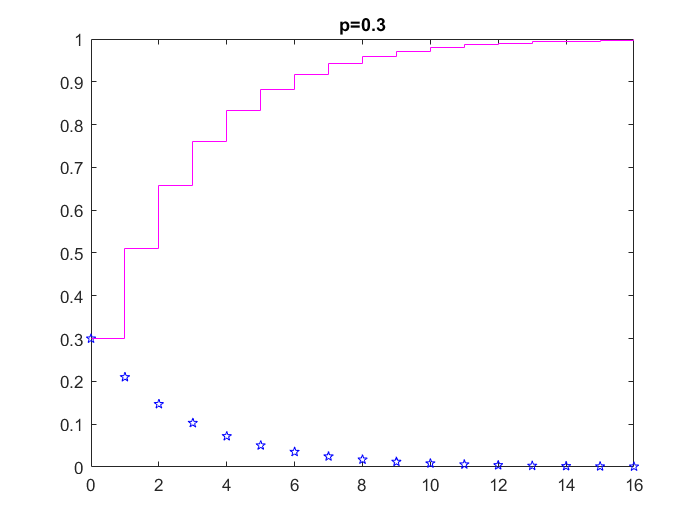

clf
x=0:1:16;
p=0.3;
plot(x,geopdf(x,p),'bp')
hold on
stairs(x,geocdf(x,p),'magenta')
title('p=0.3')
hold off

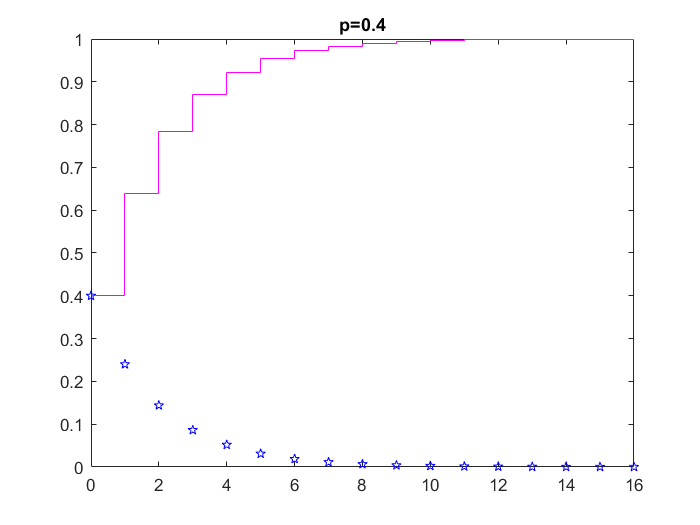


p=0.4;
plot(x,geopdf(x,p),'bp')
hold on
stairs(x,geocdf(x,p),'magenta')
title('p=0.4')

hold off

## Problema 3

Aceleasi cerinte ca si la problema 2, dar pentru legea binomiala de parametrii n ¸si p (dati de utilizator).

Indicatii: Alegeti vectorul absciselor x = 0 : n. Date de test: n = 7, p = 0.3.

clf
title('Problema 3')
message1= "Dati n: ";
n=input(message1)

n = 7

x = 0:n;
message2= "Dati p: ";
p=input(message2)

p = 0.3000

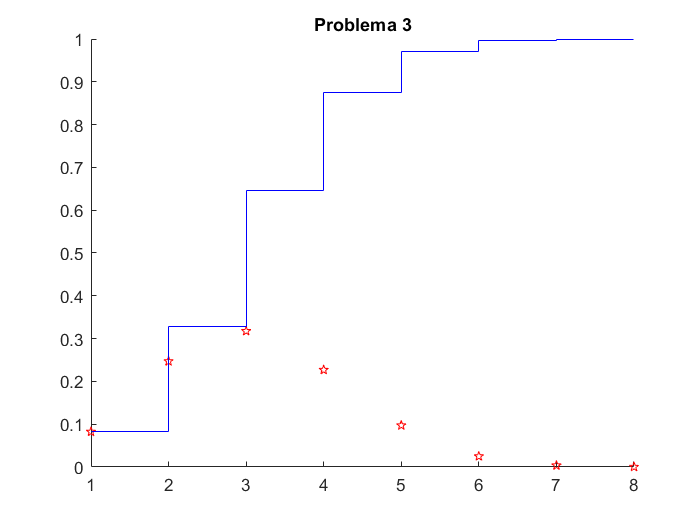


hold on;

plot(x,binopdf(x,n,p), "rp")


stairs(x,binocdf(x,n,p),"blue")

## Problema 4

Aceleasi cerinte ca si la problema 2, dar pentru legea Poisson de parametru lambda (dat de utilizator). 

clf
title('Problema 4')
message= "Dati lambda= ";
lambda=input(message)

lambda = 10

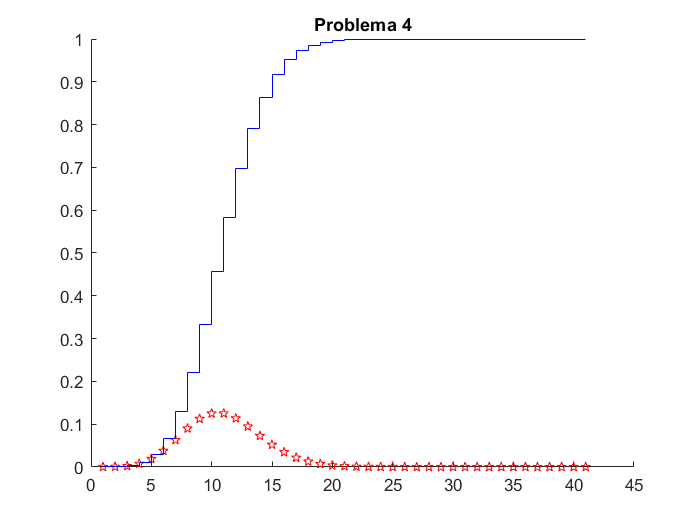

x = 0:4*lambda;

hold on;
plot(x,poisspdf(x,lambda), "rp")
stairs(x,poisscdf(x,lambda),"blue")

## Problema 5

Sa se traseze graficul densitatii de probabilitate (pdf) ¸si a functiei de repartitie (cdf ) a unei variabile aleatoare X care urmeaza legea Student (T) de parametru n (dat de utilizator). Sa se foloseasca ”regula celor 3σ” pentru a crea aceste grafice.

Indicatii: Alegeti vectorul absciselor x = m−3∗σ : 0.01 : m+3∗σ, unde m = E(X), σ = p Var(X). Date de test: n = 100.

clf
message= "Dati n: ";
n=input(message)

n = 100


[m, sigma]=tstat(n)

m = 0

sigma = 1.0204

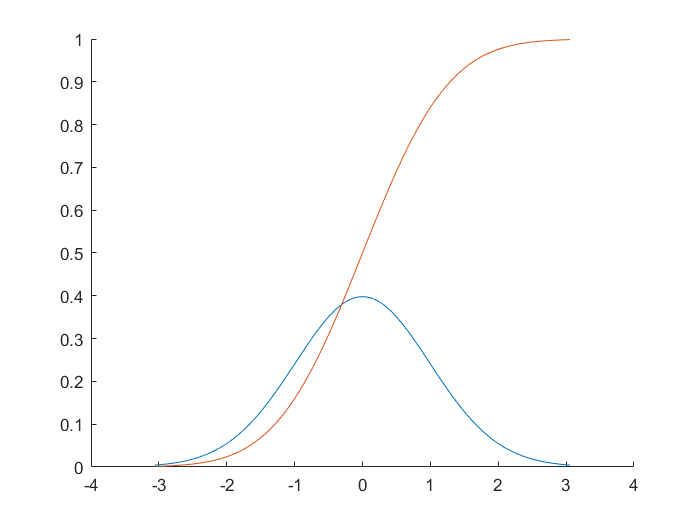

x= m-3*sigma : 0.01 : m+3*sigma;

hold on;

plot(x,tpdf(x,n))
plot(x,tcdf(x,n))

## Problema 6

Aceleasi cerinte ca si la problema 5, dar pentru legea normala de parametrii m ¸si σ (dati de utilizator).

Alegeti vectorul absciselor x = m−3∗σ : 0.01 : m+3∗σ, unde m = E(X), σ = p V ar(X). Date de test: m = 3, σ = 1. 

clf
title('Problema 6')
message1= "Dati m= ";
m=input(message1)

m = 3

message2= "Dati sigma= ";
sigma=input(message2)

sigma = 1

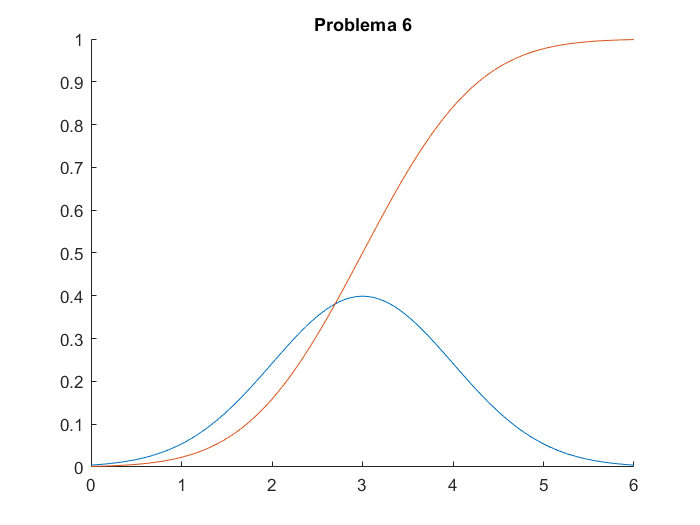


x= m-3*sigma : 0.01 : m+3*sigma;

hold on;

plot(x,normpdf(x,m,sigma))
plot(x,normcdf(x,m,sigma))

## Problema 7

Aceleasi cerinte ca si la problema 5, dar pentru legea exponentiala de parametru lambda (dat de utilizator). 

clf
title('Problema 7')

message2= "Dati lambda= "

message2 = "Dati lambda= "

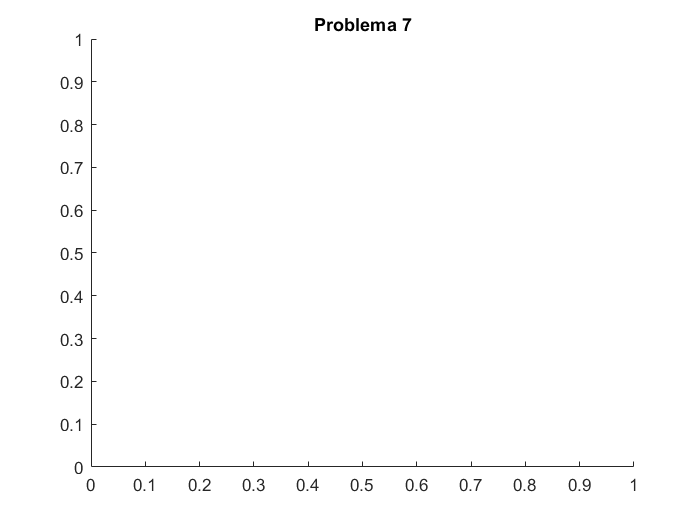

lambda = 10

lambda=input(message2)


[m, sigma]=expstat(lambda)

m = 10

sigma = 100

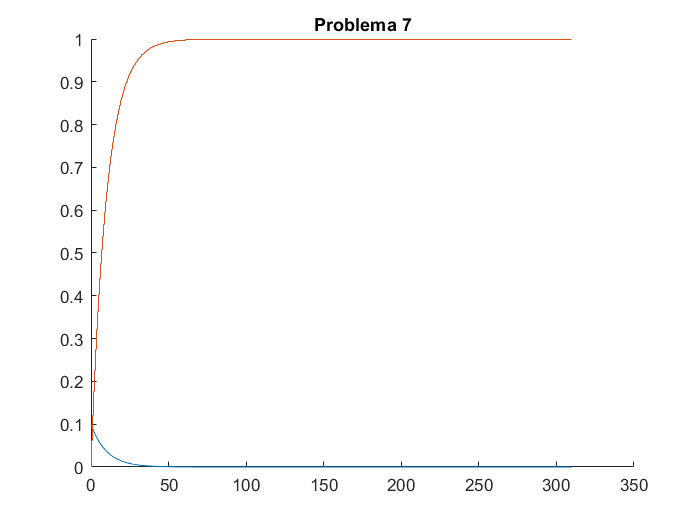

x= max(0,m-3*sigma) : 0.01 : m+3*sigma;

hold on;

plot(x,exppdf(x,lambda))
plot(x,expcdf(x,lambda))